clear all; close all; clc;

sample_count = 9

sample_count = 2

width = 424;
height = 240;

path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

glare_tensor = zeros(height,width,sample_count);

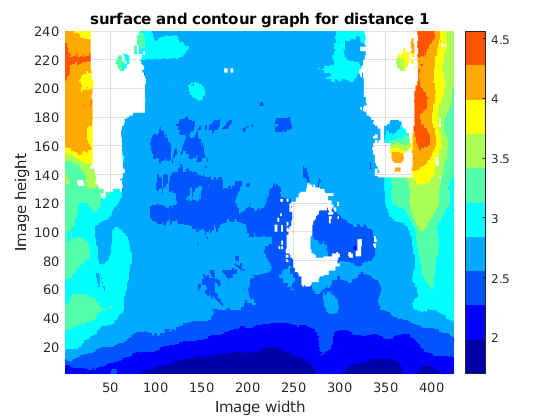

for callback_count = 1:sample_count
    
    h = string(callback_count);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    individual_callbacks = zeros(height,width);
    dist_val = data(:,4);
    
    i=1;
    for x_val = 1:height
        for y_val = 1:width
            individual_callbacks(x_val,y_val) = dist_val(i);
            i = i+ 1;
        end
    end
    
    individual_callbacks = flipud(individual_callbacks);
    glare_tensor(:,:,callback_count) = individual_callbacks;
    
    if(callback_count<=1)
        z_label = "distance";
        save_ = h;
        title_ = "surface and contour graph for "+z_label+" "+save_;
        
        plotter(width,height,individual_callbacks,title_,z_label,save_,0)
        
    end
end

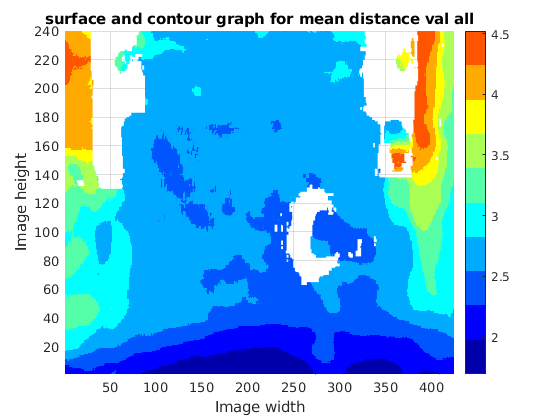

mean_map = nanmean(glare_tensor,3);
z_label = "mean distance val";
save_ = "all";
title_ = "surface and contour graph for "+z_label+" "+save_;
plotter(width,height,mean_map,title_,z_label,save_,0)

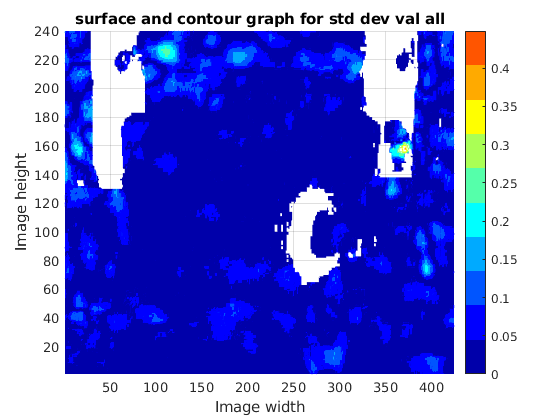

stddev_map = nanstd(glare_tensor,[],3);
z_label = "std dev val";
save_ = "all";
title_ = "surface and contour graph for "+z_label+" "+save_;
z_lim = 0.25;
plotter(width,height,stddev_map,title_,z_label,save_,z_lim)

no_of_nan_mat = zeros(size(mean_map));
for h=1:height
    for w=1:width
        temp_3d = glare_tensor(h,w,:);
        temp_1d = reshape(temp_3d, [1,sample_count]);
        no_of_nan_mat(h,w) = sum(isnan(temp_1d));
    end
end
no_of_nan_mat = sample_count*ones(size(no_of_nan_mat)) - no_of_nan_mat;
z_label = "number of nan";
save_ = "all";
title_ = "surface and contour graph for "+z_label+" "+save_;
plotter(width,height,no_of_nan_mat,title_,z_label,save_,z_lim)

Z_score_matrix = classifyPoint(mean_map,stddev_map,no_of_nan_mat)

Unrecognized function or variable 'no_of_nan_mat'.

z_label = "Z scores";
save_ = "all";
title_ = "surface and contour graph for "+z_label+" "+save_;
plotter(width,height,Z_score_matrix,title_,z_label,save_,0)

no_of_plots_for_distribution = 10

xy_index_matrix = rand(2,no_of_plots_for_distribution);
xy_index_matrix(1,:) = ceil(xy_index_matrix(1,:)*239);
xy_index_matrix(2,:) = ceil(xy_index_matrix(2,:)*423)

for i=1:no_of_plots_for_distribution
    vec_of_points = glare_tensor(xy_index_matrix(1,i),xy_index_matrix(2,i),:);
    vec_of_point = reshape(vec_of_points, [1,sample_count]);
    pointDistribution(vec_of_point,xy_index_matrix(1,i),xy_index_matrix(2,i),sample_count);
    
end


function Z_score_matrix = classifyPoint(mean_map,stddev_map,no_of_nan_mat)
syms x_var;
% 500mm -> 3mm | 1000mm -> 5mm | 1500mm -> 9mm | 2000mm -> 15mm 
% 2500mm -> 23mm | 3000mm -> 33mm | 3500mm -> 45mm | 4000mm -> 60mm
%  coefficients : 

x = [500, 1000, 1500, 2000, 2500, 3000, 3500, 4000];
y = [3,5,9,15,23,33,45,60];

x = x/1000;
y = y/1000;
p = polyfit(x,y,2)

func_ = 0.0042*x_var^2 - 0.0026*x_var + 0.0034;
fplot(func_,[0.5,7]);

Z_score_matrix = zeros(size(mean_map));
mean_map
stddev_map
ground_truth_matrix = 0.0042.*mean_map.*mean_map - 0.0026.*mean_map+0.0034.*ones(size(mean_map));
ground_truth_matrix - 2*ground_truth_matrix

difference_matrix = 1000*(ground_truth_matrix - mean_map)

sq_rt_no_of_nan_mat = no_of_nan_mat.^0.5;
intermediate_mat = (ground_truth_matrix - mean_map).*sq_rt_no_of_nan_mat;

Z_score_matrix = intermediate_mat./stddev_map;
max(Z_score_matrix)

end


function pointDistribution(point_vec,height,width,sample_count)
figure
height
width
no_of_nan = sum(isnan(point_vec))
if(no_of_nan<sample_count)
    histfit(point_vec,25,'normal')
else
    t = "all values Nan so distribution plot not possible"
end
end


function plotter(width,height,individual_callbacks,title_,z_label,save_,z_lim)

if(z_lim == 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    grid on
    view(2)
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end

if(z_lim ~= 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    zlim([0,z_lim]);
    grid on
    view(2)
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end

% saveas(gcf,title_+".png")
end







